Continuous vs discrete

clear all; close all; clc;
syms f t
f = sin(t)

$$f = \sin\left(t\right)$$

f_der = diff(f,t)

$$f\_der = \cos\left(t\right)$$


n = 100;
t_dis = linspace(0,2*pi,n);
f_dis = sin(t_dis);

dif_f_dis = gradient(f_dis,t_dis)

dif_f_dis =     0.9993    0.9973    0.9913    0.9813    0.9673    0.9494    0.9277    0.9023    0.8733    0.8407    0.8047    0.7655    0.7232    0.6781    0.6301    0.5797    0.5269    0.4720    0.4151    0.3566    0.2967    0.2356    0.1735    0.1108    0.0475   -0.0159   -0.0792   -0.1422   -0.2047   -0.2663   -0.3268   -0.3861   -0.4438   -0.4997   -0.5535   -0.6052   -0.6544   -0.7010   -0.7448   -0.7855   -0.8231   -0.8574   -0.8882   -0.9155   -0.9391   -0.9588   -0.9748   -0.9868   -0.9948   -0.9988


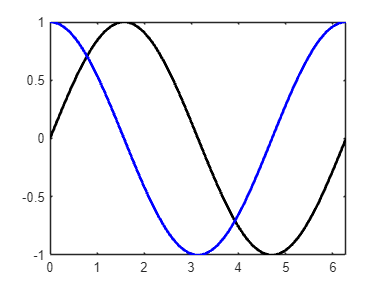


% for i = 1:length(f_dis)-1
%     dif_f_dis = f_dis(i+1)-f_dis/(1);
% end

    % diff(f_dis,t_dis);
figure
fplot(f,[0,2*pi],'-k','LineWidth',2)
hold on
fplot(f_der,[0,2*pi],'-b','LineWidth',2)
hold off

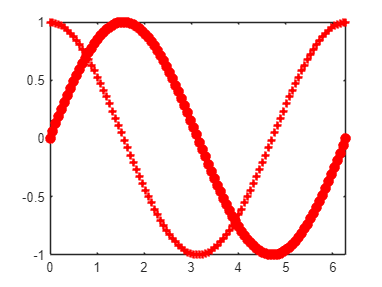


figure
plot(t_dis,f_dis,'--or','LineWidth',2,'MarkerFaceColor','r')
hold on
plot(t_dis,dif_f_dis,'+r','LineWidth',2,'MarkerFaceColor','r')
hold off

Reconstruction

coeff =     0.0923   -0.8696    1.8797   -0.1836


f_dis_polyfit =    -0.1836   -0.0677    0.0412    0.1435    0.2391    0.3283    0.4112    0.4880    0.5587    0.6236    0.6827    0.7363    0.7844    0.8272    0.8648    0.8974    0.9251    0.9481    0.9665    0.9804    0.9900    0.9955    0.9968    0.9944    0.9881    0.9783    0.9649    0.9483    0.9285    0.9056    0.8798    0.8513    0.8201    0.7865    0.7505    0.7124    0.6721    0.6300    0.5861    0.5406    0.4936    0.4453    0.3957    0.3451    0.2936    0.2412    0.1883    0.1348    0.0811    0.0270


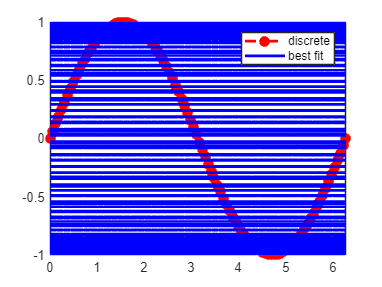

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

help polyfit